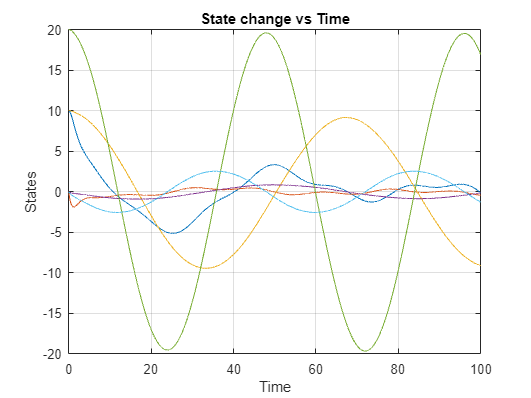

% Clear the workspace and close all figures
clc; clear; close all;
t_span = 0:0.01:100;
% Solve the ODE and obtain the state vector
[t, x] = ode45(@nonlinear_lqg, t_span, [10; 0; 10; 0; 20; 0;0;0;0;0;0;0]);


figure;
plot(t, x(:, 1));
hold on;
plot(t, x(:, 2));
plot(t, x(:, 3));
plot(t, x(:, 4));
plot(t, x(:, 5));
plot(t, x(:, 6));
xlabel('Time');
ylabel('States');
title('State change vs Time');
grid on;
hold off;

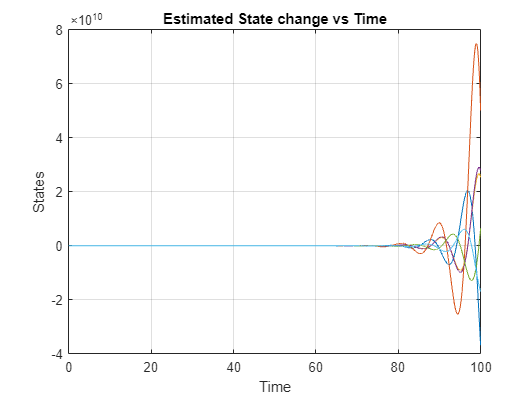

figure;
plot(t, x(:, 7));
hold on;
plot(t, x(:, 8));
plot(t, x(:, 9));
plot(t, x(:, 10));
plot(t, x(:, 11));
plot(t, x(:, 12));
xlabel('Time');
ylabel('States');
title('Estimated State change vs Time');
grid on;
hold off;

function x_dot = nonlinear_lqg(t, x)
    x_dot = zeros(6,1);
    syms M m1 m2 l1 l2 g
% g = 9.81; 
A = [0 1 0 0 0 0;
     0 0 (-g*m1)/M 0 (-g*m2)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M+m1))/(M*l1) 0 -(g*m2)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(g*m1)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B = [0;
    1/M;
    0;
    1/(M*l1);
    0;
    1/(M*l2)];

    % C Matrix 
    C_01 = [1 0 0 0 0 0];

    D = 0;

    %Defining the Mass and lengths
    M_val = 1000;
    m1_val = 100;
    m2_val = 100;
    l1_val = 20;
    l2_val = 10;
    g_val = 9.81;
    A = double(subs(A, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));
    B = double(subs(B, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));

    
    Q = [1000 0 0 0 0 0;  %x penalize
     0 1000 0 0 0 0;  %x_dot penalize
     0 0 1 0 0 0;   %theta1 penalize
     0 0 0 1 0 0;   %theta1_dot penalize
     0 0 0 0 1 0;   %theta2 penalize
     0 0 0 0 0 1];  %theta2_dot penalize
    % Q =eye(6)*100;
    R = 0.001;
    [K,~,~] = lqr(A, B, Q, R);
    F = -K*x(1:6);
    vd=0.2*eye(6); %process noise
    vn=1; %measurement noise
    
    k1 = lqr(A',C_01',vd,vn);
    sd = (A-k1'*C_01)*x(7:12);

    x_dot(1) = x(2);
    x_dot(2) = (-(m1_val*g_val*sind(x(3))*cosd(x(5))) -(m2_val*g_val*sind(x(5))*cosd(x(5))) -(m1_val*l1_val*(x(4))*(x(4))*sind(x(3))) -(m2_val*l2_val*(x(6))*(x(6))*sind(x(5))) +F)/(M_val +m1_val*(1-cosd(x(3))^2) +m2_val*(1-cosd(x(5))^2));
    x_dot(3) = x(4);
    x_dot(4) = (x_dot(2)*cosd(x(3))-g_val*(sind(x(3))))/l1_val';
    x_dot(5) = x(6);
    x_dot(6) = (x_dot(2)*cosd(x(5))-g_val*(sind(x(5))))/l2_val';
    x_dot(7) = x(2) - x(10);
    x_dot(8) = x_dot(2) - sd(2);
    x_dot(9) = x(4) - x(11);
    x_dot(10) = x_dot(4) - sd(4);
    x_dot(11) = x(6) - x(12);
    x_dot(12) = x_dot(6) - sd(6);
end
